# Filtros: Ahora es personal

## Importar datos

load("../../Utils4SP/Datasets/S9_Filtros.mat");

## Filtro Savitzky-Golay

- Aplicar S.G. 

- Calcular los coeficientes y guardarlos

- Aplicar promedio móvil

- Comparar en tiempo y en frecuencia

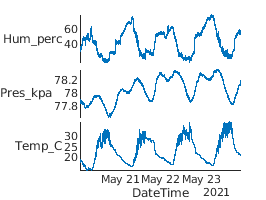

figure
stackedplot(atmosfera(:,["DateTime" "Hum_perc" "Pres_kpa" "Temp_C"]),'XVariable',"DateTime");

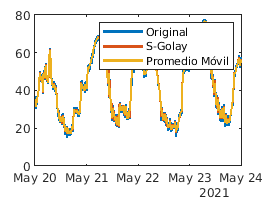


atmosfera_sg=sgolayfilt(atmosfera{:,["Hum_perc" "Pres_kpa" "Temp_C"]},2,101);
atmosfera_movmean=movmean(atmosfera{:,["Hum_perc" "Pres_kpa" "Temp_C"]},101);

figure
plot(atmosfera.DateTime,[atmosfera.Hum_perc atmosfera_sg(:,1) atmosfera_movmean(:,1)],'LineWidth',2)
legend("Original","S-Golay","Promedio Móvil")

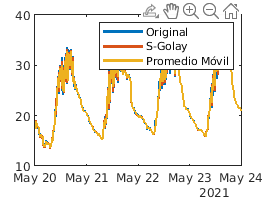


figure
plot(atmosfera.DateTime,[atmosfera.Temp_C atmosfera_sg(:,3) atmosfera_movmean(:,3)],'LineWidth',2)
legend("Original","S-Golay","Promedio Móvil")

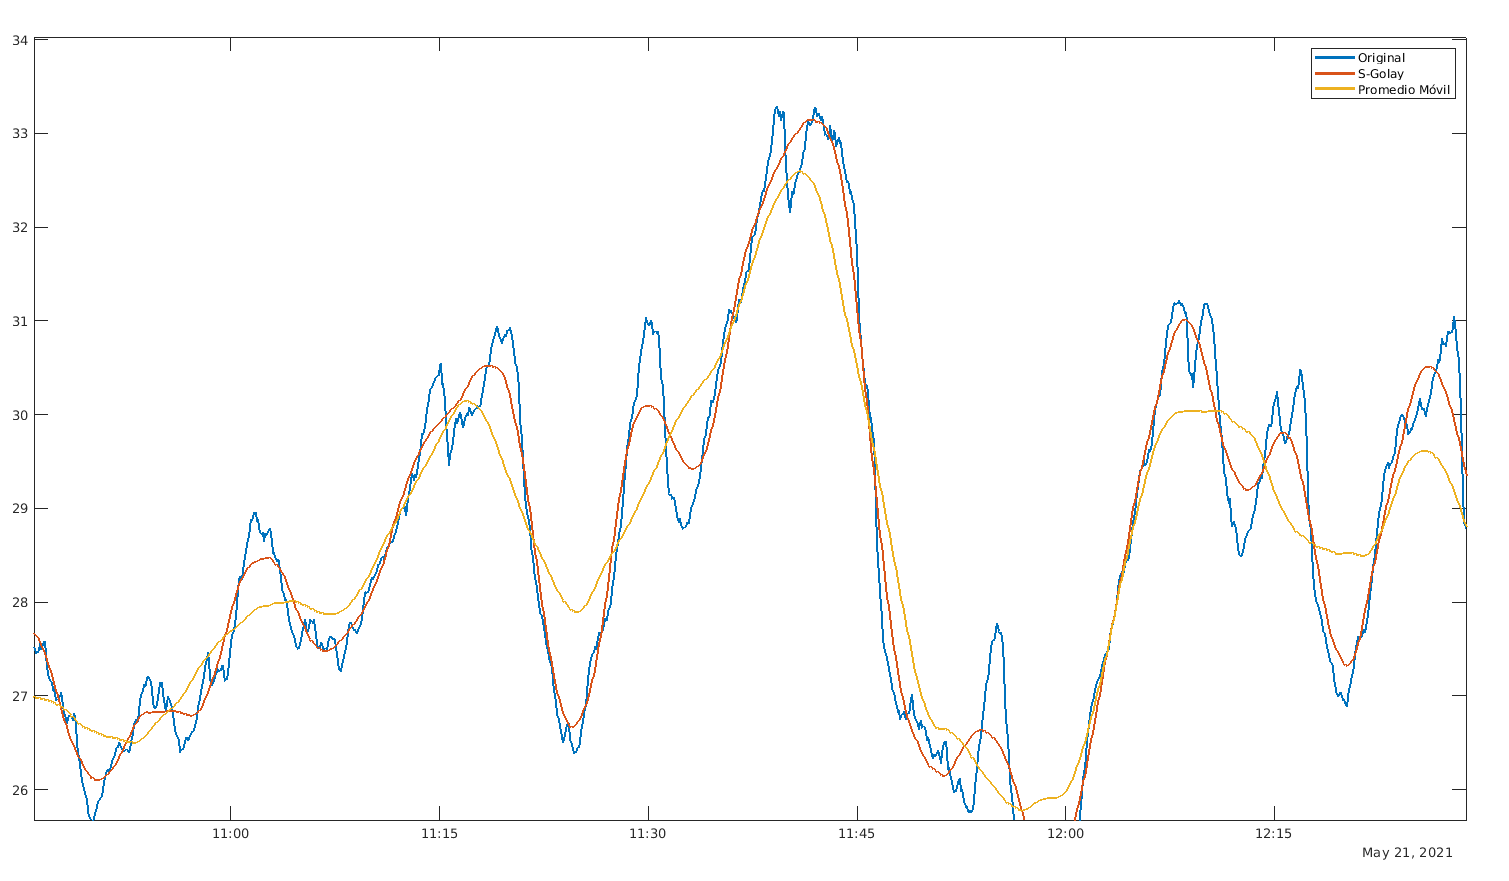

Acercamiento a las transiciones del campo de temperatura. Se observa que el filtro SGolay conserva los valles y picos, mientras que el promedio móvil los rechaza.

## Diseño de filtros